# Exercício 1

alínea a)

p_ir=0.7; %Tendo estado presente na aula anterior, probabilidade de ir
p_ir_n=0.8; %Não tendo estado presente na aula anterior, probabilidade de ir
m=[0.7 0.8 ; 0.3 0.2];

v=[1;0];
v2=m^2*v;
disp("a) Probabilidade pedida " +v2(1)+".");

a) Probabilidade pedida 0.73.


alínea b)

v=[0;1];
resp_b=m^2*v;
disp("b) Probabilidade pedida " +resp_b(1));

b) Probabilidade pedida 0.72


alínea c)

v=[1;0];
v=m^29*v;
disp("c) Probabilidade pedida " +v(1));

c) Probabilidade pedida 0.72727


alínea d)

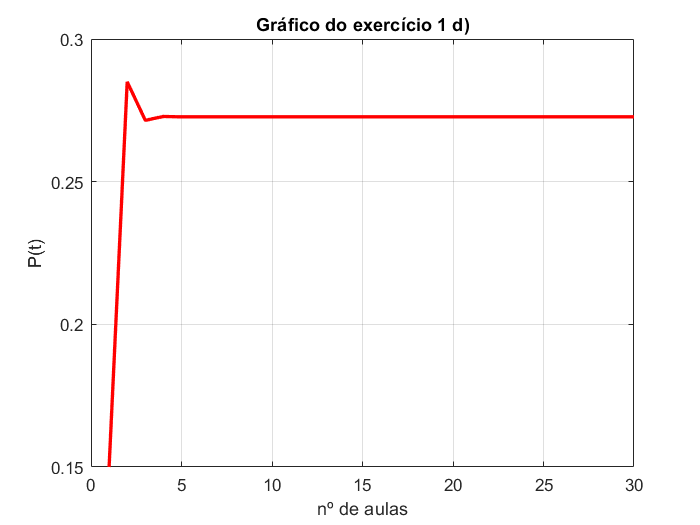

resultados=zeros(1,30);
v=[0.85;0.15];
resultados(1)=v(2);

for i=2:30
    v=m*v;
    resultados(i)=v(2);
end

plot(1:30,resultados, "r", "LineWidth",2);
grid on;
xlabel("nº de aulas");
ylabel("P(t)");
title("Gráfico do exercício 1 d)");

# Exercício 2

%3 grupos A B C
%1/3 grupo A -> grupo B
%1/3 grupo A -> grupo C
%1/4 grupo B -> grupo A
%1/5 grupo B -> grupo C
%1/2 grupo C -> grupo B
%1/2 grupo C -> grupo C


- alínea a)

m= [1/3 1/4 0;
    1/3 11/20 1/2; 
    1/3 1/5 1/2]

m =     0.3333    0.2500         0
    0.3333    0.5500    0.5000
    0.3333    0.2000    0.5000


- alínea b)

% 90 alunos
% x+y+z=90
% x=2(y+z)
% y=z
v=[60;15;15]

v =     60
    15
    15


- alínea c)

final=m^30*v;
fprintf("Grupo a: %.4f\nGrupo b: %.4f\nGrupo c: %.4f", final(1),final(2),final(3));

Grupo a: 16.6667
Grupo b: 44.4444
Grupo c: 28.8889

- alínea d)

v=[30;30;30];
final=m^30*v;
fprintf("Grupo a: %.4f\nGrupo b: %.4f\nGrupo c: %.4f", final(1),final(2),final(3));

Grupo a: 16.6667
Grupo b: 44.4444
Grupo c: 28.8889

# Exercício 3

- alínea a)

m=rand(20,20);
m=m./sum(m);
estocastica=zeros(1,20);
for i=1:20
    estocastica(1,i)=sum(m(:,i));
end
v=zeros(1,20)';
v(1)=1;


%2 transições
zara= m^2*v;
fprintf("Probabilidade de estar no estado 20 ao fim de 2 transições: %.5f",zara(20));

Probabilidade de estar no estado 20 ao fim de 2 transições: 0.05104

%5 transições
zara= m^5*v;
fprintf("Probabilidade de estar no estado 20 ao fim de 5 transições: %.5f",zara(20));

Probabilidade de estar no estado 20 ao fim de 5 transições: 0.04934

%10 transições
zara= m^10*v;
fprintf("Probabilidade de estar no estado 20 ao fim de 10 transições: %.5f",zara(20));

Probabilidade de estar no estado 20 ao fim de 10 transições: 0.04934

%100 transições
zara= m^100*v;
fprintf("Probabilidade de estar no estado 20 ao fim de 100 transições: %.5f",zara(20));

Probabilidade de estar no estado 20 ao fim de 100 transições: 0.04934

# Exercício 4

p=0.4;
q=0.6;

matriz=[p^2 (1-p)^2 p*(1-p) p*(1-p); 0 0 0 1; 0 0 0 1;q^2 q*(1-q) q*(1-q) (1-q)^2];
matriz=matriz';
v=[1;0;0;0];
fprintf('5 transições: p(A)= %.8f p(B)=%.8f p(C)=%.8f p(D)=%.8f\n', matriz^5*v);

5 transições: p(A)= 0.21034025 p(B)=0.18241782 p(C)=0.16243261 p(D)=0.44480932


fprintf('10 transições: p(A)= %.8f p(B)=%.8f p(C)=%.8f p(D)=%.8f\n', matriz^10*v);

10 transições: p(A)= 0.19794152 p(B)=0.18208110 p(C)=0.15834001 p(D)=0.46163737


fprintf('100 transições: p(A)= %.8f p(B)=%.8f p(C)=%.8f p(D)=%.8f\n', matriz^100*v);

100 transições: p(A)= 0.19788918 p(B)=0.18205805 p(C)=0.15831135 p(D)=0.46174142


fprintf('200 transições: p(A)= %.8f p(B)=%.8f p(C)=%.8f p(D)=%.8f\n', matriz^200*v);

200 transições: p(A)= 0.19788918 p(B)=0.18205805 p(C)=0.15831135 p(D)=0.46174142



h=[matriz-eye(4);ones(1,4)];
a=[zeros(4,1);1];
v=h\a;
fprintf('Limites: p(A)= %.8f p(B)=%.8f p(C)=%.3f p(D)=%.8f\n', v);

Limites: p(A)= 0.19788918 p(B)=0.18205805 p(C)=0.158 p(D)=0.46174142


# Exercício 5

alínea a)

matriz=[0.7 0.2 0.3; 
        0.2 0.3 0.3; 
        0.1 0.5 0.4];
v=[1;0;0];
final2=matriz^2*v;
disp("b) Probabilidade de estar sol no segundo dia "+(1*matriz(1,1)*matriz(1,1)));

b) Probabilidade de estar sol no segundo dia 0.49


p=1*matriz(1,1)*matriz(1,1)+1*matriz(1,1)*matriz(2,1) +1*matriz(1,2)*matriz(2,2);
disp("c) Probabilidade de não chover ao final de 2 dias é de " + p);

c) Probabilidade de não chover ao final de 2 dias é de 0.69



resultados=zeros(3,31);
resultados(:,1)=v;

for i=2:31
    resultados(:,i)=matriz^(i-1)*v;
end

final=sum(resultados,2);
disp("Número médio dias de sol "+final(1)+ ", número médio dias de nuvens "+ final(2)+ ", número médio dias de chuva " +final(3));

Número médio dias de sol 15.1488, número médio dias de nuvens 7.5309, número médio dias de chuva 8.3203



v=[0;0;1];
resultados=zeros(3,31);
resultados(:,1)=v;
for i=1:31
    resultados(:,i)=matriz^(i-1)*v;
end
final=sum(resultados,2);
disp("Número médio dias de sol "+final(1)+ ", número médio dias de nuvens "+ final(2)+ ", número médio dias de chuva " +final(3));

Número médio dias de sol 13.4539, número médio dias de nuvens 7.7004, número médio dias de chuva 9.8457


%alínea f)
% 0.1 -> dias de sol
% 0.3 -> dias de nuvens
% 0.5 -> dias de chuva
matriz=[0.7 0.2 0.3; 
        0.2 0.3 0.3; 
        0.1 0.5 0.4];
resultados=zeros(3,31);
v=[1;0;0]; % matriz quando o dia é de sol
resultados(:,1)=v;
for i=2:31
    resultados(:,i)=matriz^(i-1)*v;
end
%resultados=resultados';
final=sum(resultados,2);
n_dias=final(1)*0.1+final(2)*0.3+final(3)*0.5;
disp("Esta pessoa vai sofrer de dores reumáticas " +n_dias+ " dias no mês de janeiro, quando o primeiro dia é de sol.");

Esta pessoa vai sofrer de dores reumáticas 7.9343 dias no mês de janeiro, quando o primeiro dia é de sol.



%%%%%%%%%%%%%%%%%%%%%
resultados=zeros(3,31);
resultados(:,1)=v;
v=[0;0;1];%primeiro dia de chuva
for i=2:31
    resultados(:,i)=matriz^(i-1)*v;
end
%resultados=resultados';
final=sum(resultados,2);
n_dias=final(1)*0.1+final(2)*0.3+final(3)*0.5;
disp("Esta pessoa vai sofrer de dores reumáticas " +n_dias+ " dias no mês de janeiro, quando o primeiro dia é de chuva.");

Esta pessoa vai sofrer de dores reumáticas 8.1784 dias no mês de janeiro, quando o primeiro dia é de chuva.


# Exercício 6

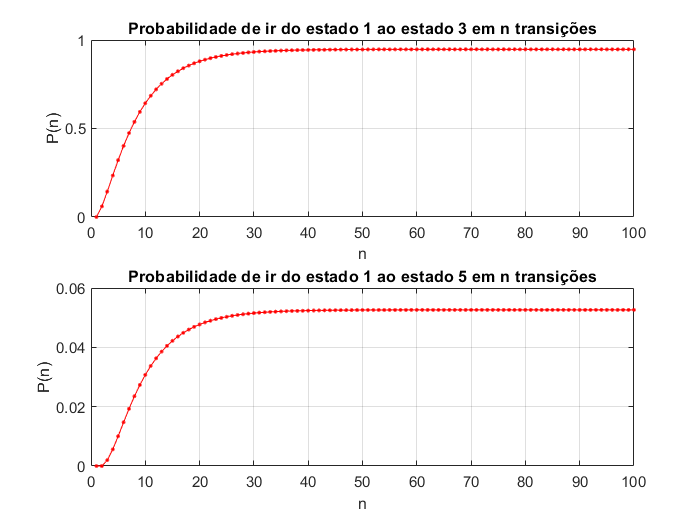

T=[0.8 0 0 0.3 0;
    0.2 0.6 0 0.2 0;
    0 0.3 1 0 0;
    0 0.1 0 0.4 0;
    0 0 0 0.1 1;];

v=[1;0;0;0;0];
resultados=zeros(1,100);

for n=1:100
    posicao=T^n*v;
    resultados(n)=posicao(2);
end
plot(1:100, resultados, "r.-");
xlabel("n");
ylabel("P(n)");
grid on;
title("Probabilidade de ir do estado 1 ao estado 2 em n transições");


%%%estado 3
resultados=zeros(1,100);
for n=1:100
    posicao=T^n*v;
    resultados(n)=posicao(3);
end
subplot(2,1,1);
plot(1:100, resultados, "r.-");
xlabel("n");
ylabel("P(n)");
grid on;
title("Probabilidade de ir do estado 1 ao estado 3 em n transições");

%%%estado 5
resultados=zeros(1,100);
for n=1:100
    posicao=T^n*v;
    resultados(n)=posicao(5);
end
subplot(2,1,2);
plot(1:100, resultados, "r.-");
xlabel("n");
ylabel("P(n)");
grid on;
title("Probabilidade de ir do estado 1 ao estado 5 em n transições");


T1=T(1:2, 1:2);
T2 = T(1:2, 4);
T3=T(4, 1:2);
T4=T(4,4);
Q=[T1,T2;T3,T4]

Q =     0.8000         0    0.3000
    0.2000    0.6000    0.2000
         0    0.1000    0.4000



F=inv(eye(size(Q))-Q)

F =     5.7895    0.7895    3.1579
    3.1579    3.1579    2.6316
    0.5263    0.5263    2.1053



fprintf("Começando em 1: %f, começando em 2: %f, começando em 3: %f", sum(F));

Começando em 1: 9.473684, começando em 2: 4.473684, começando em 3: 7.894737


R=T(4:5,1:3);
B=R*F;
[B(1,1) B(2,1)]

ans =     0.3158         0
